# Steamboat Data Analysis

In this notebook, the data collected from our measurement campaign at Steamboat (STMB) Geyser is presented below.  In short, we measued diffuse gas emissions and carbon isotopes for methane (CH4) and carbon dioxide (CO2) at one location within the STMB site from approximately 10:30 to 16:00 on 12 Jun 2019. 

## I | Import Data

For this notebook, there are six data sources:

- **Eruption history data**: this originates from [GeyserTimes](https://geysertimes.org/retrieve.php) but was collected and entered manually into an excel file

- **Steamboat Measurement Summary**: Fluxes, Keeling Plot (KP) source isotope info, and enclosure time collected from Picarro instrument and wrangled into multi-tab excel file.  The summary data represents the fluxes amd KP carbon isotope estimates from each of the 17 measurements during the campaign

- **Wrangled measurements from STMB**: Data from the excel sheet mentioned in 2. but more data (e.g. every single concentration and isotope measurement within the enclosure period).  This data was stored in a Mat-file

- **EGM CO2** flux data at Steamboat

- **Daisy Geyser (14Jun2019)** Measurement Summary: Fluxes, Keeling Plot (KP) source isotope info, and enclosure time collected from Picarro instrument

- **Wrangled measurements from DISY (14Jun2019)**: Data from the excel sheet mentioned in 5. but more data (e.g. every single concentration and isotope measurement within the enclosure period).  This data was stored in a Mat-file

- **Daisy Geyser (06Jul2018)** Measurement Summary: Fluxes, Keeling Plot (KP) source isotope info, and enclosure time collected from Picarro instrument

- **Wrangled measurements from DISY (06Jul2018)**: Data from the excel sheet mentioned in 7. but more data (e.g. every single concentration and isotope measurement within the enclosure period).  This data was stored in a Mat-file

% 1. Load Eruption History Data
STMB_Erups      = readtable("Steamboat_Geyser_Eruptions.xlsx");

% 2. Load CRDS Load Fluxes
Import_NGBN_STMB_Fluxes

% 3. Load Steamboat CRDS Data
load("NGBN_STMB_MATFILE.mat")

% 4. Load EGM Data
EGM_names      = {'Year', 'Site', 'Group', 'Soil_Type', 'SiteNumber', 'SiteLetter', 'Lattitude', 'Longitude', ...
                  'fCO2_g_m2_hr', 'log10_fCO2_g_m2_hr', 'fCO2_g_m2_dy'};
EGM_vartypes   = {};
EGM            = readtable("EGM_CO2FluxesAllDataWithSoilTypePositiveFluxes.xlsx",                             ...
                           "Sheet", "Data",                                                                   ...
                           "PreserveVariableNames",true);
EGM.Properties.VariableNames    = EGM_names;        
EGM.Site                        = categorical(EGM.Site);
EGM.Group                       = categorical(EGM.Group);
EGM.Soil_Type                   = categorical(EGM.Soil_Type);

%5. Load DISY_14Jun2019 CRDS Fluxes
    % Import Opts
opts_DISY_14Jun2019 = spreadsheetImportOptions("NumVariables", 24);
    % Specify column names and types
opts_DISY_14Jun2019.VariableNames  = ["Group", "Location", "Soil_Classification", "Latitude", "Longitude",   ...
                                      "Date_of_Measurement", "Start_Time_of_Chamber_Enclosure",              ...
                                      "End_Time_of_Chamber_Enclosure", "Duration_of_Chamber_Enclosure",      ...
                                      "CH4_Flux", "d13CH4_source",                                           ...
                                      "LowerBound_d13CH4_source", "UpperBound_d13CH4_source", "CO2_Flux",    ...
                                      "d13CO2_source", "LowerBound_d13CO2_source",                           ...
                                      "UpperBound_d13CO2_source",                                            ...
                                      "Horita_Geothermometer_Temperature_at_Formation",                      ...
                                      "Ambient_Temperature", "Barometric_Pressure", "Soil_Moisture",         ...
                                      "Soil_Conductivity", "Soil_Tempeature_at_Surface",                     ...
                                      "Soil_Tempeature_at_6_in_depth"];
opts_DISY_14Jun2019.VariableTypes  = ["categorical", "string", "categorical", "double", "double", "datetime",...
                                      "datetime", "datetime", "double", "double", "double",                 ...
                                      "double", "double", "double", "double", "double", "double",           ...
                                      "double", "double", "double", "double", "double", "double", "double"];
opts_DISY_14Jun2019.DataRange      = "A3:X9";                                  
    % Import the data
DISY_14Jun2019_Fluxes              = readtable("DISY_14Jun2019_Measurements.xlsx", ...
                                                opts_DISY_14Jun2019, "UseExcel", false);

%6. Load DISY (14Jun2019) CRDS Data
load("DISY_14Jun2019_MATFILE.mat")
                                            
%7. Load DISY_14Jun2019 CRDS Fluxes
    % Import Opts
opts_DISY_06Jul2018 = spreadsheetImportOptions("NumVariables", 24);
    % Specify column names and types
opts_DISY_06Jul2018.VariableNames  = ["Group", "Location", "Soil_Classification", "Latitude", "Longitude",   ...
                                      "Date_of_Measurement", "Start_Time_of_Chamber_Enclosure",              ...
                                      "End_Time_of_Chamber_Enclosure", "Duration_of_Chamber_Enclosure",      ...
                                      "CH4_Flux", "d13CH4_source",                                           ...
                                      "LowerBound_d13CH4_source", "UpperBound_d13CH4_source", "CO2_Flux",    ...
                                      "d13CO2_source", "LowerBound_d13CO2_source",                           ...
                                      "UpperBound_d13CO2_source",                                            ...
                                      "Horita_Geothermometer_Temperature_at_Formation",                      ...
                                      "Ambient_Temperature", "Barometric_Pressure", "Soil_Moisture",         ...
                                      "Soil_Conductivity", "Soil_Tempeature_at_Surface",                     ...
                                      "Soil_Tempeature_at_6_in_depth"];
opts_DISY_06Jul2018.VariableTypes  = ["categorical", "string", "categorical", "double", "double", "datetime",...
                                      "datetime", "datetime", "double", "double", "double",                  ...
                                      "double", "double", "double", "double", "double", "double",            ...
                                      "double", "double", "double", "double", "double", "double", "double"];
opts_DISY_06Jul2018.DataRange      =  "A3:X12";                                  
    % Import the data
DISY_06Jul2018_Fluxes              = readtable("E:\moyoa\Documents\OneDrive - Vanderbilt\PhD_Dissertation\Data_Analysis\Picarro\Yellowstone\Jul2018\06Jul2018\DISY_06Jul2018_Measurements.xlsx", ...
                                                opts_DISY_06Jul2018, "UseExcel", false);
                                            
%8. Load DISY (06Jul2018) CRDS Data
load("DISY_06Jul2018_MATFILE.mat")

Conduct some initial cleaning of the data before beginnng the formal pre-processing

% Convert all Fluxes to "per day" (mg m-2 day-1)
    % Steamboat
STMB_Fluxes.CH4_Flux = STMB_Fluxes.CH4_Flux .* 24;
STMB_Fluxes.CO2_Flux = STMB_Fluxes.CO2_Flux .* 24;
    % Daisy (14Jun2018)
DISY_14Jun2019_Fluxes.CH4_Flux = DISY_14Jun2019_Fluxes.CH4_Flux .* 24;
DISY_14Jun2019_Fluxes.CO2_Flux = DISY_14Jun2019_Fluxes.CO2_Flux .* 24;
    % Daisy (06Jul2018)
DISY_06Jul2018_Fluxes.CH4_Flux = DISY_06Jul2018_Fluxes.CH4_Flux .* 24;
DISY_06Jul2018_Fluxes.CO2_Flux = DISY_06Jul2018_Fluxes.CO2_Flux .* 24; 

% Create eruption start and end datetime values that will be used to define the eruption within
% the time series
    % Eruption - Steamboat
eruption                = datetime(string(["12-Jun-2019 12:51:00", "12-Jun-2019 16:00:00"]),                            ...
                                           "Format", "dd-MMM-yyyy HH:mm:ss"); 
    % Eruption - Daisy (14Jun2019)
eruption_14Jun2019      = datetime(string(["14-Jun-2019 11:58:00", "14-Jun-2019 12:03:00"]),                            ...
                                           "Format","dd-MMM-yyyy HH:mm:ss");
    % Eruption01 - Daisy (06Jul2018)   
eruption01_06Jul2018    = datetime(string(["06-Jul-2018 11:28:00", "06-Jul-2018 11:31:00"]),                            ...
                                           "Format","dd-MMM-yyyy HH:mm:ss");
    % Eruption02 - Daisy (06Jul2018)   
eruption02_06Jul2018    = datetime(string(["06-Jul-2018 14:55:00", "06-Jul-2018 14:58:00"]),                            ...
                                           "Format","dd-MMM-yyyy HH:mm:ss");                                          
% Create a categorical vector that labeles measurements before and after the eruption                        
ff = find(STMB_Fluxes.End_Time_of_Chamber_Enclosure <= eruption(1));
% Pre-allocate
Erup_Status = string();
for i = 1:height(STMB_Fluxes)
    if i == 7
       Erup_Status(i)  = "Precursor";
    elseif i <= ff(end)
       Erup_Status(i)  = "Before";
    else
       Erup_Status(i)  = "After";
    end
end
% Reshape
Erup_Status = reshape(Erup_Status, [height(STMB_Fluxes), 1]);
% Add variable to table
STMB_Fluxes = addvars(STMB_Fluxes, Erup_Status, 'After', 'End_Time_of_Chamber_Enclosure');
% Switch string to categorical
STMB_Fluxes.Erup_Status = categorical(STMB_Fluxes.Erup_Status);

% Extract only the 

## II | Pre-Processing

Arrange and clean data for analysis.

### II | a | Combine the dates and time for the eruption data

% Set formats
STMB_Erups.Date.Format = 'dd-MMM-yyyy HH:mm';
STMB_Erups.Time        = datestr(datenum(STMB_Erups.Time), "HH:mm");
STMB_Erups.Time        = datetime(STMB_Erups.Time, "Input", "HH:mm");

% Merge Date and Time
Datetime               = datetime(dateshift(STMB_Erups.Date, 'start', 'day') + timeofday(STMB_Erups.Time),         ...
                                 'Format', 'dd-MMM-yyyy HH:mm');

% Add the datetime to table
STMB_Erups = addvars(STMB_Erups, Datetime, 'Before', "Date");
STMB_Erups = sortrows(STMB_Erups,"Datetime");

% Remove time column
STMB_Erups = removevars(STMB_Erups,["Date", "Time", "Num_of_Days_Since_Previous_Erup"]);
% % Clear first row
% STMB_Erups(1,:) = [];

% Convert STMB_Erups to a timetable object
STMB_Erups = table2timetable(STMB_Erups);


### II | b | Duration between each Steamboat eruption

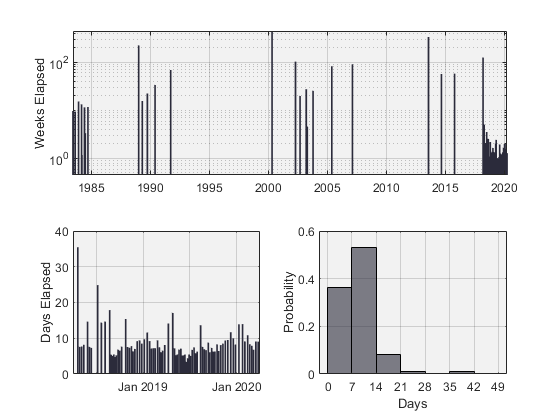

% Duration
    % Pre-allocate
days_passed = duration(nan([height(STMB_Erups),3]));
    % Calculate the number of days between each measurement and return that
    % value as a double precision object
for i = 2:height(STMB_Erups)
    days_passed(i)                                  = STMB_Erups.Datetime(i) - STMB_Erups.Datetime(i-1);
end

% Add the datetime to table
STMB_Erups.Days_Elapsed = days(days_passed);
STMB_Erups.Weeks_Elapsed= STMB_Erups.Days_Elapsed ./ 7;
    % Provide a name for days passed
%STMB_Erups.Properties.VariableNames{'Var2'} = STMB_Erups.Days_Elapsed;

% Number of eruptions since April 2018
f                       = find(STMB_Erups.Datetime >= "01-Apr-2018");
post_Apr_Erups          = STMB_Erups.Days_Elapsed(f); clearvars f
num_post_Apr_Erups      = length(post_Apr_Erups);
% Descriptive stats
mu_post_Apr_Erups       = mean(post_Apr_Erups);
sigma_post_Apr_Erups    = std(post_Apr_Erups);

% Visualization of Eruptions
    % Establish Background colors
bkgrnd_lite = [0.950 0.950 0.950];
bkgrnd_dark = [0.150 0.150 0.150];
    % Establish colormap [BW]
    bone_map = bone();
    
    % Establish colormap [full color]
    hsv_map = hsv();

    % Full timeline of eruptions
figure,
subplot(2,2,1:2)
st1  = stem(STMB_Erups.Datetime, STMB_Erups.Weeks_Elapsed); %, ':o', "MarkerFaceColor", [0.5961 0.7176 0.8314])
%title("Time Since Last Eruption at Steamboat Geyser | Yellowstone")
ylabel("Weeks Elapsed")
set(gca,"Color", bkgrnd_lite, "GridColor", 'k', 'YScale', 'log')
set(st1, 'LineWidth', 1.25, 'Marker', 'none', 'Color', bone_map(50,:)) 
grid on

subplot(2,2,3)
    % Gather index for 2018 to present
        % Start Date: 01-Jan-2018
    srt_date = "19-Apr-2018 00:00";
        % End Date: now
    end_date = "now";
    % Get Time Range
    new_STMB_idx = timerange(srt_date, end_date);
st2 = stem(STMB_Erups.Datetime(new_STMB_idx), STMB_Erups.Days_Elapsed(new_STMB_idx)); %, ':o', "MarkerFaceColor", [0.5961 0.7176 0.8314])
%title("Time Since Last Eruption | Apr 2018-Oct 2019")
ylabel("Days Elapsed")
set(gca,"Color", bkgrnd_lite, "GridColor", 'k')
set(st2, 'LineWidth', 1.25, 'Marker', 'none', 'Color', bone_map(50,:))
grid on

% Histogram of subsampled data
subplot(2,2,4)
edges = 0:7:50;
histogram(STMB_Erups.Days_Elapsed(new_STMB_idx), "Normalization", "probability", "BinEdges", edges, "FaceColor", bone_map(50,:))
%title("Days Elapsed Since Last Eruption | Apr 2018-Oct 2019")
ylabel("Probability"), xlabel("Days")
set(gca, "Color", bkgrnd_lite, "GridColor", 'k')
xticks(edges)
grid on

Figure 01*: *Steamboat Geyser eruption history. Top: Each stem indicates an eruption that corresponds to a date along the x-axis. The y-axis illustrates the number of weeks that pass between each eruption (note the log scale for the y-axis). Bottom-left: The number of days that pass between eruptions that have occurred in its most recent active phase. Bottom-right: histogram displaying the distribution of the time elapsed between eruptions during the recent active phase.

## III | Steamboat Flux Timeline

Time series of fluxes for the measuring campaign for both CH4 and CO2

### III | a | Grouped Statistics

Find the descriptive statistics for each group (e.g. before, departing value, and after the STMB eruption)

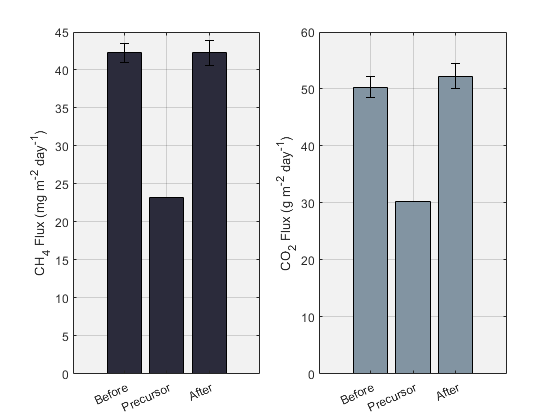

% Group and Apply Descriptive Statistics
S = findgroups(STMB_Fluxes.Erup_Status);
desc_stats      = @(x)[mean(x) std(x)];
grp_stats_CH4   = splitapply(desc_stats, STMB_Fluxes.CH4_Flux, S);
grp_stats_CO2   = splitapply(desc_stats, STMB_Fluxes.CO2_Flux./1E03, S);

figure,
% CH4
subplot(1,2,1)
% Ensure that the data are represented in the correct order
    % Before
y(1,:) = grp_stats_CH4(2,:);
    % Precursor
y(2,:) = grp_stats_CH4(3,:);    
    % After
y(3,:) = grp_stats_CH4(1,:);
b1 = bar(y(:,1));
%title('Descriptive Stats | CH_4')
ylabel('CH_4 Flux (mg m^{-2} day^{-1})')
xticklabels({'Before', 'Precursor', 'After'})
xtickangle(25)
set(gca, 'Color', bkgrnd_lite, 'Colormap', bone, 'GridColor', 'k')
set(b1(1), 'FaceColor', bone_map(050,:))
%legend({'Mean', 'Std. Deviation'}, "Location", "northwest")
hold on
eb_1 = errorbar(y(:,1), y(:,2));
eb_1.Color      = [0 0 0];
eb_1.LineStyle  = 'none';
grid on
% CO2
subplot(1,2,2)
% Ensure that the data are represented in the correct order
    % Before
yy(1,:) = grp_stats_CO2(2,:);
    % Precursor
yy(2,:) = grp_stats_CO2(3,:);    
    % After
yy(3,:) = grp_stats_CO2(1,:);
b2 = bar(yy(:,1));
%title('Before & After Eruption | CO_2')
ylabel('CO_2 Flux (g m^{-2} day^{-1})')
xticklabels({'Before', 'Precursor', 'After'})
xtickangle(25)
set(gca, 'Color', bkgrnd_lite, 'Colormap', bone, 'GridColor', 'k', 'YScale', 'linear')
set(b2(1), 'FaceColor', bone_map(150,:))
%legend({'Mean', 'Std. Deviation'}, "Location", "northwest")
hold on
eb_2 = errorbar(yy(:,1), yy(:,2));
eb_2.Color      = [0 0 0];
eb_2.LineStyle  = 'none';
grid on

Figure 02: Comparing the mean and standard deviation values of measurements before and after the geyser eruption. Note the log scale on the y-axis for the CO2 fluxes.

% Percent decline from first six measurements - CH4
x = mean(STMB_Fluxes.CH4_Flux(1:6));  y = STMB_Fluxes.CH4_Flux(7);
pct_diff_CH4 = ((x - y) / grp_stats_CH4(1,1)) .* 100;
% Percent decline from first six measurements - CO2
a = mean(STMB_Fluxes.CO2_Flux(1:6));  b = STMB_Fluxes.CO2_Flux(7);
pct_diff_CO2 = ((a - b) / grp_stats_CO2(1,1)) .* 100;

% Display a string that prints the percent difference between before and
% after fluxes
pct_diff_str = sprintf('There was a %2.2f and %2.2f increase between measurements before and after the eruption for CH4 and CO2, respectively.',       ...
                       pct_diff_CH4, pct_diff_CO2);

% Clear extraneous variables
clearvars x y a b

### III | b | Flux Time Series

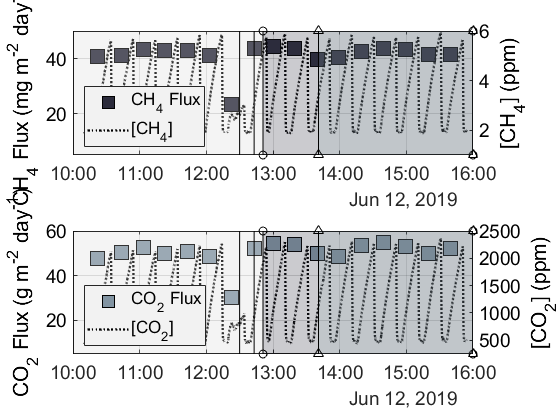

figure,
% Methane
subplot(2,1,1)
ax = gca;
% Plot the Time Series of the Fluxes and the [CH4] pn the same plot
ts_CH4 = plot(STMB_Fluxes.End_Time_of_Chamber_Enclosure, STMB_Fluxes.CH4_Flux, 'ks',                           ...
    'MarkerFaceColor', bone_map(50,:), 'MarkerSize', 13);
    %title('CH_4 Fluxes & [CH_4] vs. Time | Steamboat',                                                        ... 
    %      'FontSize', 10)
    ylabel('CH_4 Flux (mg m^{-2} day^{-1})')
    ylim([5 50])
    %set(gca, 'XTickLabel', [], 'YLim', [0, 40])
    hold on    

% Plot on the right axis
yyaxis right
plot(TT_NGBN_STMB.Time, TT_NGBN_STMB.HP_CH4_dry, ':', 'Color', bone_map(1,:),                                   ...
    'LineWidth', 1.75);
    ylabel('[CH_{4}] (ppm)')
    ax.Color            =  bkgrnd_lite;
    ax.YAxis(2).Color   = [0.000 0.00 0.000];
    ax.FontSize         =  14;
    ax.YLim             = [01 06];
    grid on
    hold on  
    
% Plot Other Events During Time Series
    % (a) Steam emissions
pre_steam       = datetime(string(["12-Jun-2019 10:00:00", "12-Jun-2019 12:30:00"]),                            ...
                                   "Format", "dd-MMM-yyyy HH:mm:ss");
plot_eruption(pre_steam, 255, "CH4")
    hold on
    % (b) Preplay expressed
pre_play        = datetime(string(["12-Jun-2019 12:30:00", "12-Jun-2019 12:43:00"]),                            ...
                                   "Format", "dd-MMM-yyyy HH:mm:ss");
plot_eruption(pre_play, 255, "CH4")
    hold on
    % (c) Minor eruptions
minor_erup      = datetime(string(["12-Jun-2019 12:43:00", "12-Jun-2019 12:51:00"]),                            ...
                                   "Format", "dd-MMM-yyyy HH:mm:ss");
plot_eruption(minor_erup, 255, "CH4")                              
    hold on                               
    % (d) Eruption - liquid dominant   
plot_eruption(eruption, 055, "CH4")
    hold on
    % (e) Liquid dominance gives way to steam dominance
steam_dom_erup  = datetime(string(["12-Jun-2019 13:41:00", "12-Jun-2019 16:00:00"]),                            ...
                                   "Format", "dd-MMM-yyyy HH:mm:ss");
plot_eruption(steam_dom_erup, 175, "CH4")
% Establish legend                               
legend({'CH_4 Flux', '[CH_4]'}, 'Location', 'southwest')      
    
% Carbon Dioxide
subplot(2,1,2)
ax2 = gca;
ts_CO2 = plot(STMB_Fluxes.End_Time_of_Chamber_Enclosure, STMB_Fluxes.CO2_Flux./1E03, 'ks',                       ...
    'MarkerFaceColor', bone_map(150,:), 'MarkerSize', 13);
    %title('CO_2 Fluxes & [CO_2] vs. Time | Steamboat',                                                          
    %      'FontSize', 10)
    ylabel('CO_2 Flux (g m^{-2} day^{-1})')
    ylim([5 60])
    %xlim([datetime("26-Oct-2017 11:30"), datetime("26-Oct-2017 19:30")])
    hold on    
    
% Plot on the right axis
yyaxis right
plot(TT_NGBN_STMB.Time, TT_NGBN_STMB.CO2_dry, ':', 'Color', bone_map(1,:),                                       ...
    'LineWidth', 1.75)
    ylabel('[CO_2] (ppm)')
    %xlim([datetime("26-Oct-2017 11:30"), datetime("26-Oct-2017 19:30")])
    ax2.Color          =  bkgrnd_lite;
    ax2.YAxis(2).Color = [0.000 0.000 0.000];
    ax2.FontSize       =  14;
    ax2.YLim           = [250 2500];    
    grid on
    hold on
    
% Plot Other Events During Time Series
    % (a) Steam emissions
plot_eruption(pre_steam, 255, "CO2")
    hold on
    % (b) Preplay expressed
plot_eruption(pre_play, 255, "CO2")
    hold on
    % (c) Minor eruptions
plot_eruption(minor_erup, 255, "CO2")                             
    hold on                               
    % (d) Eruption - liquid dominant   
plot_eruption(eruption, 055, "CO2")
    hold on
    % (e) Liquid dominance gives way to steam dominance
plot_eruption(steam_dom_erup, 175, "CO2")
% Establish legend                               
legend({'CO_2 Flux', '[CO_2]'}, 'Location', 'southwest')                             

Figure 03: Time series for CH4 and CO2fluxes (left y-axis) and 1-minute averaged continuous concentration ([CH4] and [CO2]) measurements (right y-axis) during the measuring campaign.  Shaded area designates the time period following the beginning of the eruption. Note: the mass units for CH4fluxes are in milligrams, while the CO2 fluxes are represented by grams.

### III | c | Carbon Isotopes Time Series

The carbon isotope time series, where the isotope source is estimated by using the KP method. 

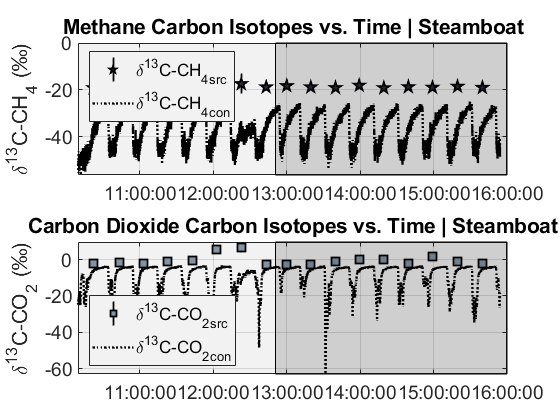

figure,
% Methane
subplot(2,1,1)
% Range of error barrs for CO2
err_range_d13CH4 = STMB_Fluxes.UpperBound_d13CH4_source - STMB_Fluxes.LowerBound_d13CH4_source;
ax = gca;
% Plot the Time Series of the Fluxes and the [CH4] pn the same plot
erbr_d13CH4_KP = errorbar(datenum(STMB_Fluxes.End_Time_of_Chamber_Enclosure),                                                 ...
                       STMB_Fluxes.d13CH4_source, err_range_d13CH4,                                                           ...
                      'kp', 'MarkerFaceColor', bone_map(050,:), 'MarkerSize', 9, 'CapSize', 0, 'LineWidth', 1.25);
    title('Methane Carbon Isotopes vs. Time | Steamboat',                                                                     ... 
          'FontSize', 10)
    ylabel('δ^{13}C-CH_4 (‰)')    
    hold on    
% Plot the isotopes as time series 
    plot(datenum(TT_NGBN_STMB.Time), TT_NGBN_STMB.HP_d13_CH4, ':', 'Color', bone_map(1,:),                                    ...
   'LineWidth', 1.75);
    ylabel('\delta^{13}C-CH_4 (‰)')  
    hold on      
% Set up the global properties
    ax.FontSize  = 14;    
    ax.Color     = bkgrnd_lite;
    xtix         =["12-Jun-2019 10:00", "12-Jun-2019 11:00", "12-Jun-2019 12:00", "12-Jun-2019 13:00",                        ...
                  "12-Jun-2019 14:00", "12-Jun-2019 15:00", "12-Jun-2019 16:00"];
    ax.XTick     = datenum(xtix);
    ax.XTickLabel = string(timeofday(datetime(xtix)));
    axis tight
    legend({'\delta^{13}C-CH_4_{src}', '\delta^{13}C-CH_4_{con}'}, "Location", "northwest")
    grid on
% Plot Eruption    
    X_area       = eruption;
    X_area       = datenum([X_area, fliplr(X_area)]);
    Y_area       =[ax.YLim(1), ax.YLim(1), 0, 0];
    fill(X_area(1,:), Y_area(1,:), bone_map(005,:), 'FaceAlpha', 0.15)
    legend({'\delta^{13}C-CH_4_{src}', '\delta^{13}C-CH_4_{con}'}, "Location", "northwest")
    
% Carbon Dioxide
subplot(2,1,2)
% Range of error barrs for CO2
err_range_d13CO2 = STMB_Fluxes.UpperBound_d13CO2_source - STMB_Fluxes.LowerBound_d13CO2_source;
% Plot errorbar plot
ax2 = gca;
erbr_d13CO2_KP   = errorbar(datenum(STMB_Fluxes.End_Time_of_Chamber_Enclosure), STMB_Fluxes.d13CO2_source,                        ...
                            err_range_d13CO2,                                                                                     ...
                           'ks', 'MarkerFaceColor', bone_map(150,:), 'MarkerSize', 9, 'CapSize', 0, 'LineWidth', 1.25);
    title('Carbon Dioxide Carbon Isotopes vs. Time | Steamboat',                                                                  ... 
          'FontSize', 10)      
    ylabel('δ^{13}C-CO_2 (‰)')
    hold on  
% Plot the isotopes as time series 
ts_d13CO2 = plot(datenum(TT_NGBN_STMB.Time), TT_NGBN_STMB.d13_CO2, ':', 'Color', bone_map(1,:),                                   ...
    'LineWidth', 1.75);
    ylabel('\delta^{13}C-CO_2 (‰)')
    ax2.FontSize= 14;
    ax2.Color   = bkgrnd_lite;
    legend({'\delta^{13}C-CO_2_{src}', '\delta^{13}C-CO_2_{con}'}, "Location", "northwest")    
    axis tight
    ax2.XTick    = datenum(xtix);
    ax2.XTickLabel = string(timeofday(datetime(xtix)));
    grid on
    hold on 
% Plot Eruption    
    X_area      = eruption;
    X_area      = datenum([X_area, fliplr(X_area)]);
    Y_area      =[ax2.YLim(1), ax2.YLim(1), ax2.YLim(2), ax2.YLim(2)];
    fill(X_area(1,:), Y_area(1,:), bone_map(005,:), 'FaceAlpha', 0.15)
    legend({'\delta^{13}C-CO_2_{src}', '\delta^{13}C-CO_2_{con}'}, "Location", "southwest")

Figure 04: Time series of subsurface source estimations for methane (d13C-CH4_src) and carbon dioxide (d13-CO2_src) over the measuring campaign.  The continuous methane (d13C-CH4_con) and carbon dioxide (d13CCO2_con) are presented here with a temporal resolution of *4 Hz*.

### III | d | Plot the resampled d13C isotope

The d13C data is plotted at 60 Hz as opposed to 4 Hz

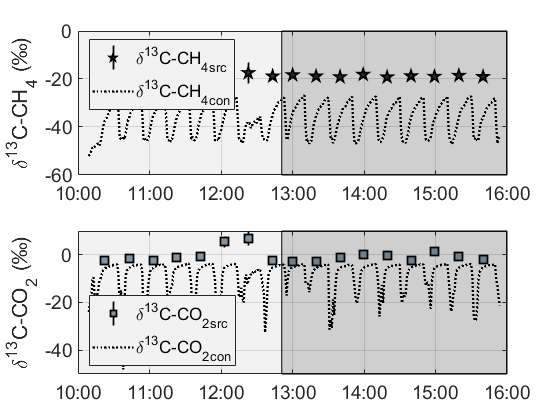

% Resample the d13C isotopes by finding the mean value every minute
TT_NGBN_STMB_resamp_1min = retime(TT_NGBN_STMB, "minutely", "mean");

% Carbon Isotopes
figure,
% Methane
subplot(2,1,1)
ax60Hz_a = gca;
% Plot the Time Series of the Fluxes and the [CH4] pn the same plot
    erbr_d13CH4_60Hz = errorbar(datenum(STMB_Fluxes.End_Time_of_Chamber_Enclosure),                                         ...
                                STMB_Fluxes.d13CH4_source, err_range_d13CH4,                                                ...
                               'kp', 'MarkerFaceColor', bone_map(050,:), 'MarkerSize', 9, 'CapSize', 0, 'LineWidth', 1.25);
    %title('Methane Carbon Isotopes vs. Time | Steamboat',                                                                   ... 
          %'FontSize', 10)
    ylabel('δ^{13}C-CH_4 (‰)')    
    hold on    
% Plot the isotopes as time series 
    plot(datenum(TT_NGBN_STMB_resamp_1min.Time), TT_NGBN_STMB_resamp_1min.HP_d13_CH4, ':', 'Color', bone_map(1,:),                      ...
   'LineWidth', 1.75);
    ylabel('\delta^{13}C-CH_4 (‰)')  
    hold on      
% Set up the global properties
    ax60Hz_a.FontSize = 14;    
    ax60Hz_a.Color    = bkgrnd_lite;
    ax60Hz_a.XLim     = [7.375884166666666e+05 7.375886666666666e+05];
    datetick('x', 15, 'keeplimits')
   %axis tight
    legend({'\delta^{13}C-CH_4_{src}', '\delta^{13}C-CH_4_{con}'}, "Location", "northwest")
    grid on
% Plot Eruption    
    X_area      = eruption;
    X_area      = datenum([X_area, fliplr(X_area)]);
    Y_area      =[ax60Hz_a.YLim(1), ax60Hz_a.YLim(1), 0, 0];
    fill(X_area(1,:), Y_area(1,:), bone_map(005,:), 'FaceAlpha', 0.15)
    legend({'\delta^{13}C-CH_4_{src}', '\delta^{13}C-CH_4_{con}'}, "Location", "northwest")
    
% Carbon Dioxide
subplot(2,1,2)
% Plot errorbar plot
ax60Hz_b = gca;
    erbr_d13CO2_60Hz = errorbar(datenum(STMB_Fluxes.End_Time_of_Chamber_Enclosure), STMB_Fluxes.d13CO2_source,                       ...
                                err_range_d13CO2,                                                                                    ...
                                'ks', 'MarkerFaceColor', bone_map(150,:), 'MarkerSize', 9, 'CapSize', 0, 'LineWidth', 1.25);
    %title('Carbon Dioxide Carbon Isotopes vs. Time | Steamboat',                                                                     ... 
          %'FontSize', 10)      
    ylabel('δ^{13}C-CO_2 (‰)')
    hold on  
% Plot the isotopes as time series 
    plot(datenum(TT_NGBN_STMB_resamp_1min.Time), TT_NGBN_STMB_resamp_1min.d13_CO2, ':', 'Color', bone_map(1,:),                      ...
   'LineWidth', 1.75);
    ylabel('\delta^{13}C-CO_2 (‰)')
    ax60Hz_b.FontSize= 14;
    ax60Hz_b.Color   = bkgrnd_lite;
    ax60Hz_b.XLim    = ax60Hz_a.XLim;
    datetick('x', 15, 'keeplimits')
   %axis tight    
    grid on
    hold on 
% Plot Eruption    
    X_area      = eruption;
    X_area      = datenum([X_area, fliplr(X_area)]);
    Y_area      =[-50, -50, 10, 10];
    fill(X_area(1,:), Y_area(1,:), bone_map(005,:), 'FaceAlpha', 0.15)
    legend({'\delta^{13}C-CO_2_{src}', '\delta^{13}C-CO_2_{con}'}, "Location", "southwest")

Figure 05: Time series of subsurface source estimations for d13C-CH4_src and d13-CO2_src over the measuring campaign.  Measurements of d13C-CH4_con and d13CCO2_con are presented here with a temporal resolution of *60 Hz*.

### III | e | Last 10 measurements for Carbon Isotope Estimate

Plot the isotope estimates using the mean of the last ten measurements from each chamber enclosure

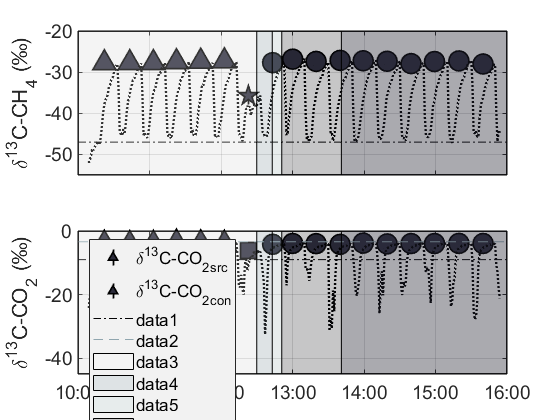

% Separate the last *TEN* measurements of every enclosure period
    % 
sz_ChamON = size(NGBN_STMB_ChamON);
ChamON_slc= cell([sz_ChamON(3), 1]);
var_names = {'Rel_Sec', 'HP_CH4_dry', 'HR_CH4_dry', 'HP_d13_CH4', 'HR_d13_CH4', 'CO2_dry', 'd13_CO2', 'Alarm_Status',...
             'CH4_mg_m3', 'CO2_mg_m3'};
mu_10_d13CH4 = nan([sz_ChamON(3) 2]);
mu_10_d13CO2 = nan([sz_ChamON(3) 2]);         
for i = 1:sz_ChamON(3)
  % Find the indices for the last ten non-NAN values
  [f, fi]       = find(~isnan(NGBN_STMB_ChamON(:,5,i)), 10, 'last');
  % Use the indices from the inquiry in the previous line (f) to get the
  % relevant data
   ChamON_slc{i}= NGBN_STMB_ChamON(f(1):f(end), :, i);
  % Extract the the datenum data
   ChamON_dte   = ChamON_slc{i}(:,1);
  % Convert datenum data to datetime object
   ChamON_dte   = datetime(datestr(ChamON_dte, 'dd-mmm-yyyy HH:MM:SS'));
  % Add datetime and numeric data into a timetable objet
   ChamON_TT    = timetable(ChamON_dte,                                                                             ...
                            ChamON_slc{i}(:,02), ChamON_slc{i}(:,03), ChamON_slc{i}(:,04), ChamON_slc{i}(:,05),     ...
                            ChamON_slc{i}(:,06), ChamON_slc{i}(:,07), ChamON_slc{i}(:,08), ChamON_slc{i}(:,09),     ...
                            ChamON_slc{i}(:,10), ChamON_slc{i}(:,11),                                               ...
                           'VariableNames', var_names);
   ChamON_slc{i}= ChamON_TT;
  % Quantify the mean and std. deviation values of the 10 d13CH4 and d13CO2 data
  % (use the function handle from previous section for mean and std. dev
  % calculation
      mu_10_d13CH4(i,:) = desc_stats(ChamON_slc{i}.HP_d13_CH4);
      mu_10_d13CO2(i,:) = desc_stats(ChamON_slc{i}.d13_CO2);
end

% Using the "last ten" carbon istope estmates, visualize the data with a time series similar to that
% of the Keeling Plot carbon isotope estimate

% Carbon Isotopes - *Last 10*
figure,
% Methane
subplot(2,1,1)
axL10_a = gca;
% Plot the Time Series of the Carbon Isotopes over time
for i = 1:height(STMB_Fluxes)
    erbr_d13CH4_L10 = errorbar(datenum(STMB_Fluxes.End_Time_of_Chamber_Enclosure(i)),                                          ...
                               mu_10_d13CH4(i,1), mu_10_d13CH4(i,2),                                                        ...
                              'kp', ...
                              'MarkerSize', 6, 'CapSize', 0,                      ...
                              'LineWidth', 1.25);
   set(erbr_d13CH4_L10, 'MarkerFaceColor', bone_map(050,:))
    % Provide symbols for measurements before, precursor, and after major
    % eruption   
   if i < 7
      erbr_d13CH4_L10.Marker = "^";
    elseif i == 7
      erbr_d13CH4_L10.Marker = "pentagram";
    else
      erbr_d13CH4_L10.Marker = "o";
   end
   hold on
end
    %title('Methane Carbon Isotopes vs. Time | Steamboat','FontSize', 10)
    ylabel('δ^{13}C-CH_4 (‰)')    
    hold on
    
% Plot the isotopes as time series 
    plot(datenum(TT_NGBN_STMB_resamp_1min.Time), TT_NGBN_STMB_resamp_1min.HP_d13_CH4, ':',                                  ...
                'Color', bone_map(1,:),                                                                                     ...
                'LineWidth', 1.75); 
    ylabel('\delta^{13}C-CH_4 (‰)')  
    hold on 
    
% Set up the global properties
    axL10_a.FontSize    = 14;    
    axL10_a.Color       = bkgrnd_lite; 
    axL10_a.XLim        = [7.375884166666666e+05 7.375886666666666e+05];
    datetick('x', 15, 'keeplimits')
    axL10_a.XTickLabels = [];
    axL10_a.YLim        = [-55 -20];
    %axis tight 
    grid on
% Atmospheric reference line
    CH4_ref             = refline([0 -47]);
    CH4_ref.LineStyle   = '-.';    
    CH4_ref.Color       = 'k';
% Plot Eruption    
    % (a) Pre steam    
    X_area      = pre_steam;
    X_area      =datenum([X_area, fliplr(X_area)]);
    Y_area      =[axL10_a.YLim(1), axL10_a.YLim(1), axL10_a.YLim(2), axL10_a.YLim(2)];
    fill(X_area(1,:), Y_area(1,:), bone_map(255,:), 'FaceAlpha', 0.20, 'LineStyle', '-')
    hold on
    
    % (b) Pre Play  
    X_area      = pre_play;
    X_area      =datenum([X_area, fliplr(X_area)]);
    Y_area      =[axL10_a.YLim(1), axL10_a.YLim(1), axL10_a.YLim(2), axL10_a.YLim(2)];
    fill(X_area(1,:), Y_area(1,:), bone_map(165,:), 'FaceAlpha', 0.20, 'LineStyle', '-')
    hold on
    
    % (c) 
    X_area      = minor_erup;
    X_area      =datenum([X_area, fliplr(X_area)]);
    Y_area      =[axL10_a.YLim(1), axL10_a.YLim(1), axL10_a.YLim(2), axL10_a.YLim(2)];
    fill(X_area(1,:), Y_area(1,:), bone_map(205,:), 'FaceAlpha', 0.20, 'LineStyle', '-')
    hold on
    
    % (d) Liquid-Dominated Phase eruption
    X_area      = eruption;
    X_area      =datenum([X_area, fliplr(X_area)]);
    Y_area      =[axL10_a.YLim(1), axL10_a.YLim(1), axL10_a.YLim(2), axL10_a.YLim(2)];
    fill(X_area(1,:), Y_area(1,:), bone_map(025,:), 'FaceAlpha', 0.20, 'LineStyle', '-')
    hold on
    
    % (e) Steam-Dominated Phase eruption
    X_area      = steam_dom_erup;
    X_area      =datenum([X_area, fliplr(X_area)]);
    Y_area      =[axL10_a.YLim(1), axL10_a.YLim(1), axL10_a.YLim(2), axL10_a.YLim(2)];
    fill(X_area(1,:), Y_area(1,:), bone_map(065,:), 'FaceAlpha', 0.20, 'LineStyle', '-')
    %legend({'\delta^{13}C-CO_2 - estimate', '\delta^{13}C-CO_2 - continuous'},                          ...
           %"Location", "southwest", "NumColumns", 2)
    
% Carbon Dioxide
subplot(2,1,2)
% Plot errorbar plot
axL10_b = gca;
    erbr_d13CO2_L10 = errorbar(datenum(STMB_Fluxes.End_Time_of_Chamber_Enclosure),                                          ...
                               mu_10_d13CO2(:,1), mu_10_d13CO2(:,2),                                                        ...
                              'ks', 'MarkerFaceColor', bone_map(150,:), 'MarkerSize', 6, 'CapSize', 0,                      ...
                              'LineWidth', 1.50);
for i = 1:height(STMB_Fluxes)
    erbr_d13CO2_L10 = errorbar(datenum(STMB_Fluxes.End_Time_of_Chamber_Enclosure(i)),                                       ...
                               mu_10_d13CO2(i,1), mu_10_d13CO2(i,2),                                                        ...
                              'kp',                                                                                         ...
                              'MarkerSize', 6, 'CapSize', 0,                                                                ...
                              'LineWidth', 1.25);
   set(erbr_d13CO2_L10, 'MarkerFaceColor', bone_map(050,:))
    % Provide symbols for measurements before, precursor, and after major
    % eruption   
   if i < 7
      erbr_d13CO2_L10.Marker = "^";
    elseif i == 7
      erbr_d13CO2_L10.Marker = "square";
    else
      erbr_d13CO2_L10.Marker = "o";
   end
   hold on
end
    %title('Carbon Dioxide Carbon Isotopes vs. Time | Steamboat', 'FontSize', 10) 
    ylabel('δ^{13}C-CO_2 (‰)')
    hold on  
    
% Plot the isotopes as time series 
    plot(datenum(TT_NGBN_STMB_resamp_1min.Time), TT_NGBN_STMB_resamp_1min.d13_CO2, ':', 'Color', bone_map(1,:),             ...
    'LineWidth', 1.75);
    ylabel('\delta^{13}C-CO_2 (‰)')
    axL10_b.FontSize        = 14;
    axL10_b.Color           = bkgrnd_lite;
    legend({'\delta^{13}C-CO_2_{src}', '\delta^{13}C-CO_2_{con}'}, "Location", "northwest")    
    axL10_b.YLim            = [-45 0];
    axL10_b.XLim            = axL10_a.XLim;
    datetick('x', 15, 'keeplimits')    
    grid on
    hold on 
% Atmospheric reference line
    CO2_atm_ref             = refline([0 -9]);
    CO2_atm_ref.LineStyle   = '-.';
    CO2_atm_ref.Color       = bone_map(005,:);
% Mantle reference line
    CO2_mtl_ref             = refline([0 -3.4]);
    CO2_mtl_ref.LineStyle   = '--';
    CO2_mtl_ref.Color       = bone_map(165,:);       
% Plot Eruption 
    % (a) Pre steam    
    X_area      = pre_steam;
    X_area      =datenum([X_area, fliplr(X_area)]);
    Y_area      =[-45, -45, 0, 0];
    fill(X_area(1,:), Y_area(1,:), bone_map(255,:), 'FaceAlpha', 0.20, 'LineStyle', '-')
    hold on
    
    % (b) Pre Play  
    X_area      = pre_play;
    X_area      =datenum([X_area, fliplr(X_area)]);
    Y_area      =[-45, -45, 0, 0];
    fill(X_area(1,:), Y_area(1,:), bone_map(165,:), 'FaceAlpha', 0.20, 'LineStyle', '-') 
    hold on
    
    % (c) 
    X_area      = minor_erup;
    X_area      =datenum([X_area, fliplr(X_area)]);
    Y_area      =[-45, -45, 0, 0];
    fill(X_area(1,:), Y_area(1,:), bone_map(205,:), 'FaceAlpha', 0.20, 'LineStyle', '-')
    hold on
    
    % (d) Liquid-Dominated Phase eruption
    X_area      = eruption;
    X_area      =datenum([X_area, fliplr(X_area)]);
    Y_area      =[-45, -45, 0, 0];
    fill(X_area(1,:), Y_area(1,:), bone_map(025,:), 'FaceAlpha', 0.20, 'LineStyle', '-')
    hold on
    
    % (e) Steam-Dominated Phase eruption
    X_area      = steam_dom_erup;
    X_area      =datenum([X_area, fliplr(X_area)]);
    Y_area      =[-45, -45, 0, 0];
    fill(X_area(1,:), Y_area(1,:), bone_map(065,:), 'FaceAlpha', 0.20, 'LineStyle', '-')

    %legend({'\delta^{13}C-CO_2 - estimate', '\delta^{13}C-CO_2 - continuous'},                                                                 ...
           %"Location", "southwest", "NumColumns", 2)

Figure 06: Time series of isotope source estimates using the mean of the last ten values.  Continuous isotope measurements are presented at a frequency of 60 Hz.  Also, the horizontal line across both plots indicates the atmospheric carbon isotopic composition reference line.

## Extra Plots

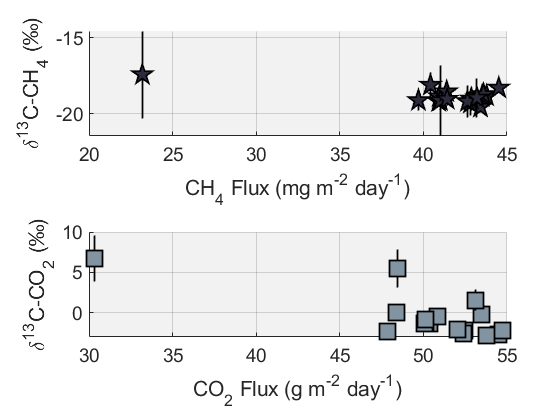


%--- KP Estimate ---%
% Isotope Signatures v Fluxes
figure,
tiledlayout('flow')
% d13C-CH4 (KP) v CH4 Fluxes 
nexttile
clr = bone(height(STMB_Fluxes));
hold on
for i = 1:height(STMB_Fluxes)
    eb_a = errorbar(STMB_Fluxes.CH4_Flux(i), STMB_Fluxes.d13CH4_source(i),                      ...
                err_range_d13CO2(i),                                                                 ...
               'kp',                                                                                 ...
               'MarkerSize', 16, 'CapSize', 0, 'LineWidth', 1.25);
    set(eb_a,'MarkerFaceColor', bone_map(050,:))
end
%title('CH_4 Fluxes vs \delta^{13}C-CH_4')
ylabel('\delta^{13}C-CH_4 (‰)'), xlabel('CH_4 Flux (mg m^{-2} day^{-1})')
set(gca, 'FontSize', 14, 'Color', bkgrnd_lite, 'GridColor', 'k')
%colormap bone
grid on

% d13C-CO2 (KP) v CO2 Fluxes 
nexttile
clr = bone(height(STMB_Fluxes));
hold on
for i = 1:height(STMB_Fluxes)
    eb_b = errorbar(STMB_Fluxes.CO2_Flux(i)/1E03, STMB_Fluxes.d13CO2_source(i),                       ...
                err_range_d13CO2(i),                                                                  ...
               'ks',                                                                                  ...
               'MarkerSize', 16, 'CapSize', 0, 'LineWidth', 1.25);
    set(eb_b,'MarkerFaceColor',bone_map(150,:))
end
%title('CO_2 Fluxes vs \delta^{13}C-CO_2')
ylabel('\delta^{13}C-CO_2 (‰)'), xlabel('CO_2 Flux (g m^{-2} day^{-1})')
set(gca, 'FontSize', 14, 'Color', bkgrnd_lite, 'GridColor', 'k')
%cb2 = colorbar; cb2.Label.String = 'Measurement Number'; 
%cb2.Ticks = linspace(0,1,9); cb2.TickLabels = {'1', '3', '5', '7', '9', '11', '13', '15', '17'};
%colormap bone
grid on

Figure 07: Paired d13C and flux measurements.  The d13C measurements estimate the stable carbon isotope composition of the subsurface source using the Keeling Plot method. The error bars indicate the bounds at a 95% level of confidence. Shading presents the sequence of the measurements with respect to time, where the darker colors indicate ealier in the time series and lighter represent the end. 

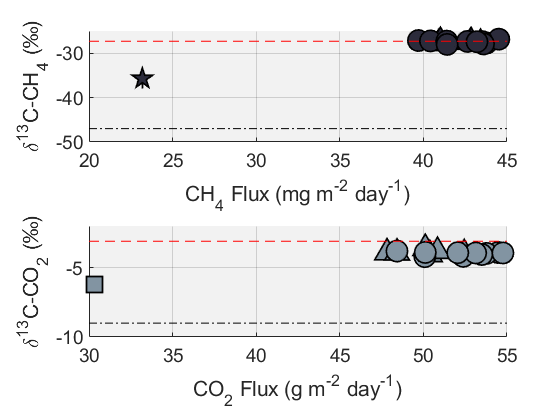


%--- L10 Estimate ---%
% Isotope Signatures v Fluxes
figure,
tiledlayout('flow')
% d13C-CH4 (KP) v CH4 Fluxes 
nexttile
clr = bone(height(STMB_Fluxes));
hold on
for i = 1:height(STMB_Fluxes)
    eb_c = errorbar(STMB_Fluxes.CH4_Flux(i), mu_10_d13CH4(i,1),                                     ...
                mu_10_d13CH4(i,2),                                                                  ...
               'kp',                                                                                ...
               'MarkerSize', 16, 'CapSize', 0, 'LineWidth', 1.25);
    set(eb_c,'MarkerFaceColor', bone_map(050,:))
    if i < 7
      eb_c.Marker = "^";
    elseif i == 7
      eb_c.Marker = "pentagram";
    else
      eb_c.Marker = "o";
    end
end
%title('CH_4 Fluxes vs \delta^{13}C-CH_4')
ylabel('\delta^{13}C-CH_4 (‰)'), xlabel('CH_4 Flux (mg m^{-2} day^{-1})')
set(gca, 'FontSize', 14, 'Color', bkgrnd_lite, 'GridColor', 'k', 'ylim', [-50 -25])
%legend(eb_c, {'Before', 'Precursor', 'After'})
%colormap bone
hold on
% Plot Reference Lines
    % Atmospheric reference line
    CH4_ref             = refline([0 -47]);
    CH4_ref.LineStyle   = '-.';    
    CH4_ref.Color       = 'k';
    % Fumarole reference line
    fum_ref             = refline([0 -27.3]);
    fum_ref.LineStyle   = '--';    
    fum_ref.Color       = 'r';    
    
grid on

% d13C-CO2 (KP) v CO2 Fluxes 
nexttile
clr = bone(height(STMB_Fluxes));
hold on
for i = 1:height(STMB_Fluxes)
    eb_d = errorbar(STMB_Fluxes.CO2_Flux(i)/1E03, mu_10_d13CO2(i,1),                                ...
                mu_10_d13CO2(i,2),                                                                  ...
               'ks',                                                                                ...
               'MarkerSize', 16, 'CapSize', 0, 'LineWidth', 1.25);
    set(eb_d,'MarkerFaceColor',bone_map(150,:))
    if i < 7
      eb_d.Marker = "^";
    elseif i == 7
      eb_d.Marker = "square";
    else
      eb_d.Marker = "o";
    end
end
%title('CO_2 Fluxes vs \delta^{13}C-CO_2')
ylabel('\delta^{13}C-CO_2 (‰)'), xlabel('CO_2 Flux (g m^{-2} day^{-1})')
set(gca, 'FontSize', 14, 'Color', bkgrnd_lite, 'GridColor', 'k', 'ylim', [-10 -2])
%legend(eb_d, {'Before', 'Precursor', 'After'})
%cb2 = colorbar; cb2.Label.String = 'Measurement Number'; 
%cb2.Ticks = linspace(0,1,9); cb2.TickLabels = {'1', '3', '5', '7', '9', '11', '13', '15', '17'};
%colormap bone
hold on
% Plot Reference Lines
    % Atmospheric reference line
    CO2_atm_ref             = refline([0 -9]);
    CO2_atm_ref.LineStyle   = '-.';
    CO2_atm_ref.Color       = 'k';
    % Fumarole reference line   
    fum_ref                 = refline([0 -3.1]);
    fum_ref.LineStyle       = '--';    
    fum_ref.Color           = 'r';      

grid on

% Export the isotopic data to a .csv file
    % Extract data to table
%L10_iso_tbl = table(t(:,1), t(:,2), mu_10_d13CH4(:,1), mu_10_d13CH4(:,2), mu_10_d13CO2(:,1), mu_10_d13CO2(:,2),         ...
                   %'VariableNames', {'Start_Time_of_Chamber_Enclosure', 'End_Time_of_Chamber_Enclosure', 'L10_d13CH4',  ...
                   %'L10_d13CH4_1SE', 'L10_d13CO2', 'L10_d13CO2_1SE'});

    % Write to .csv
%writetable(L10_iso_tbl, "E:\moyoa\Documents\OneDrive - Vanderbilt\PhD_Dissertation\Data_Analysis\Picarro\Yellowstone\Jun2019\12Jun2019\Steamboat_L10_d13C.csv")

Figure 08:  Paired d13C and flux measurements. The d13C data estimate the stable carbon isotope composition of the gas escaping from the subsurface using the last ten measurements of the chamber enclosure. The error bars are 1 standard deviation from the mean of the ten values. Shading presents the sequence of the measurements with respect to time, where the darker colors indicate ealier in the time series and lighter

### Keeling Plot  

Create three Keeling plots to highlight how we would use the plot to estimate carbon isotopic composition of the subsurface source.  To do this, the homemade function, KPlot, will be used.

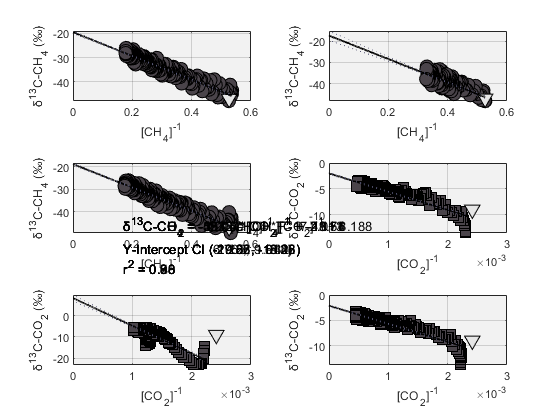

% Slice out the data needed for these three charts
xData   = [NGBN_STMB_ChamON(:,3,3), NGBN_STMB_ChamON(:,3,7), NGBN_STMB_ChamON(:,3,14),                                  ...
           NGBN_STMB_ChamON(:,7,3), NGBN_STMB_ChamON(:,7,7), NGBN_STMB_ChamON(:,7,14)];
yData   = [NGBN_STMB_ChamON(:,5,3), NGBN_STMB_ChamON(:,5,7), NGBN_STMB_ChamON(:,5,14),                                  ...
           NGBN_STMB_ChamON(:,8,3), NGBN_STMB_ChamON(:,8,7), NGBN_STMB_ChamON(:,8,14)];

% Pre allocate output
mdl     = cell([size(xData,2), 1]);
coef    = cell([size(xData,2), 1]);
figure,
tiledlayout('flow')
for i   = 1:size(xData,2)
    nexttile
    if i <= 3
    [m, c]      = KPlot(xData(:,i), yData(:,i), 'CH4', 'bw');
    else
    [m, c]      = KPlot(xData(:,i), yData(:,i), 'CO2', 'bw');        
    end
    mdl{i}     = m;
    coef{i}    = c;
end

Figure 09: Keeling plots for select measurements.  Methane is pictured by the circular symbols and is presented in the top row, whereas carbon dioxde is depicted by square symbols and displayed in the bottom row.  The thick black line is the linear regression model that is written out in text within the legend, and the thin dotted lines on either side represent the 95% confidence interval (CI) for the linear model. 

### Isostope Comparison

Using a plot modelled after a figure presented by Whiticar (1999), the following will compare the CO2 and CH4 carbon isotope compositions per chamber enclosure.  Here, there are only three graphs presented just as the Keeling Plots above.

rows are greater than columns


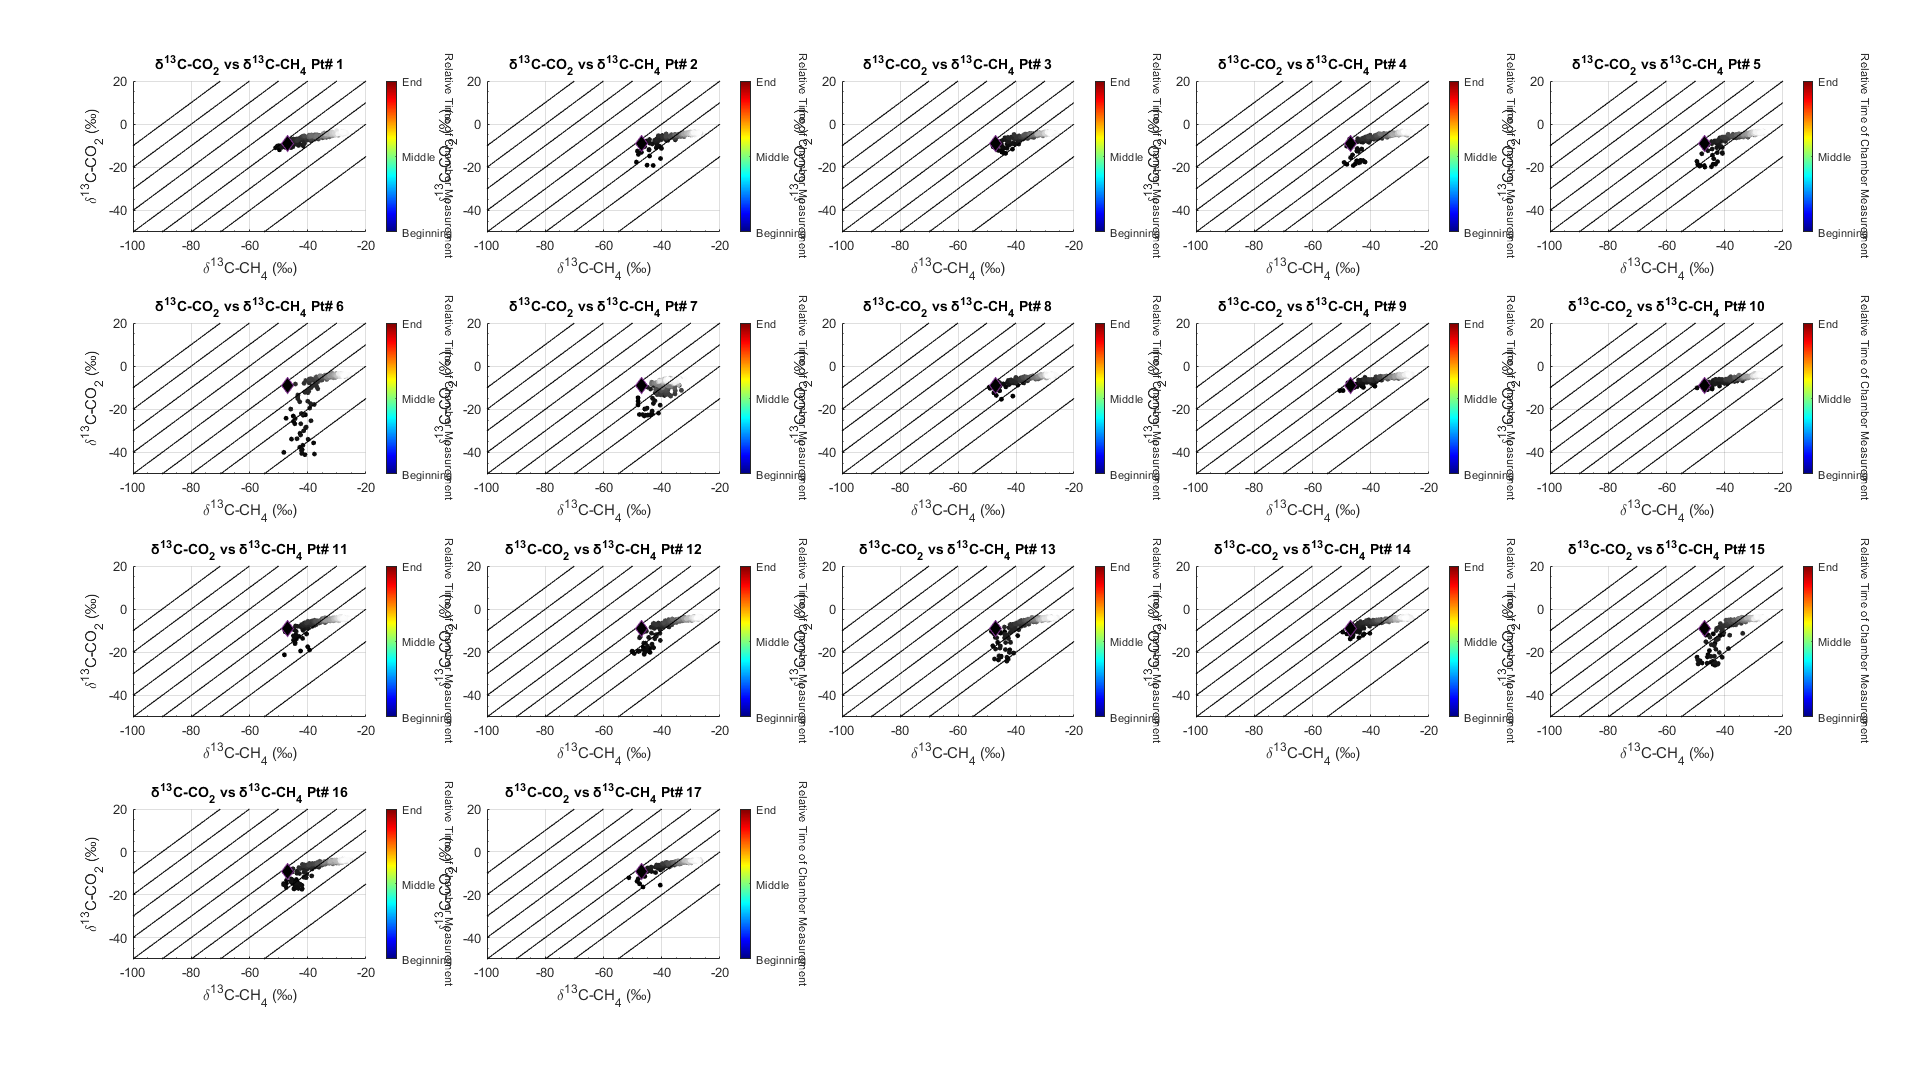

ans =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'none'
    MarkerFaceColor: 'flat'
           SizeData: 14
          LineWidth: 0.5000
              XData: [1×257 double]
              YData: [1×257 double]
              ZData: [1×0 double]
              CData: [257×3 double]

  Show all properties


nchams = 17;
% Isolate the isotopic data
iCH4 = NGBN_STMB_ChamON(:,5,:); iCO2 = NGBN_STMB_ChamON(:,8,:);

% Use the isocomp_array() to plot the iCO2 vs. iCH4 data
isocomp_array(iCH4, iCO2, ceil(5/2), 4, nchams) 

## IV | EGM Data

Using a previously made function EGM_Reducer(), extact and sort the EGM data measureed at Steamboat

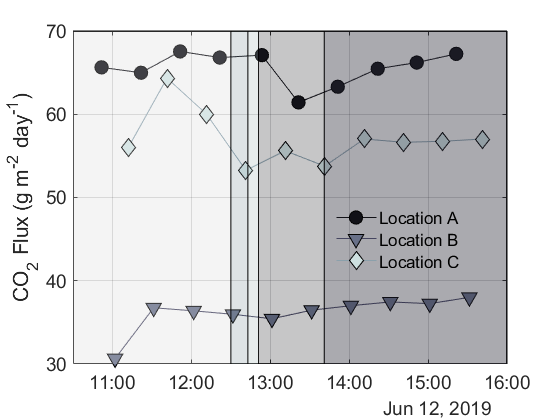

% Initialize the filepath for the EGM data
EGM5_raw_file = "E:\moyoa\Documents\OneDrive - Vanderbilt\PhD_Dissertation\Data_Analysis\Picarro\Yellowstone\EGM_Data_YNP\2019\19_06_12_STMB.xlsx";

% Execute the EGM_Reducer() function on the data file
[T_sum, T_all, T_cell] = EGM5_Reducer(EGM5_raw_file);

% Using the summary table, get rid of rows with NaN values
T_sum = rmmissing(T_sum);

% Remove measurements with enclosure times below zero and above three
% minutes
for i = 1:height(T_sum)
    if T_sum.dt(i) < duration(0,0,0) || T_sum.dt(i) > duration(0,3,0)
       T_sum(i, :) = [];
    end
end

% Based on visual inspection and JCA's notes, subtract one hour from the
% timestamps so that they are correct
T_sum.start_date    = T_sum.start_date - hours(1);
T_sum.end_date      = T_sum.end_date   - hours(1); 

% Apply the location of each chamber measurement according to JCA's notes
    % Set up an empty string array as a new column, 'Location'
Location = strings([height(T_sum), 1]);
    % Using visual inspection of JCA's notes, add the correct Location in
    % the proper sequence
i = 1;     
while  i  < height(T_sum) 
    % This conditional is set up using knowledge from JCA's notes
    if i == height(T_sum)
        break
    elseif T_sum.plot_num(i) < 95
        i               = i + 1;    
    elseif T_sum.plot_num(i) >= 95 && T_sum.plot_num(i) <= 124
        Location(i)     = "A";
        Location(i+1)   = "B";
        Location(i+2)   = "C";
        i               = i + 3;
    end
end

% Make 'Location' a categorical variable
    % Turn <undefined> into "missing"
Location(1:5)           = "missing";
Location                = categorical(Location);
% Add Location to summary table
T_sum                   = addvars(T_sum, Location, 'After', 'end_date');

% Trim data to only include measurements with locations (indices hard-coded
% with visual inspection)
egm_grp_tbl             = T_sum(6:end, :);
    % Multiply flux measurements by 24 to convert units to g CO2 m-2 day-1
egm_grp_tbl.srl_rate    = egm_grp_tbl.srl_rate .* 24;
egm_grp_tbl.srq_rate    = egm_grp_tbl.srq_rate .* 24;
% Visualize the data 
figure,
gs = gscatter(egm_grp_tbl.end_date, egm_grp_tbl.srl_rate, egm_grp_tbl.Location);
%title('CO_2 Fluxes (EGM-5) chamber')
ylabel('CO_2 Flux (g m^{-2} day^{-1})')
set(gca  , 'Color', bkgrnd_lite, 'GridColor', 'k', 'FontSize', 14, 'ylim', [30, 70],                                               ...
   'xlim', [datetime('12-Jun-2019 10:30'), datetime('12-Jun-2019 16:00')])
set(gs(1), 'LineStyle', '-', 'Color', bone_map(020,:),                                                                             ...
   'MarkerEdgeColor', 'k', 'Marker',  "o", "MarkerFaceColor", bone_map(020,:), "MarkerSize", 10)
set(gs(2), 'LineStyle', '-', 'Color', bone_map(080,:),                                                                             ...
   'MarkerEdgeColor', 'k', 'Marker',  "v", "MarkerFaceColor", bone_map(120,:), "MarkerSize", 10)
set(gs(3), 'LineStyle', '-', 'Color', bone_map(160,:),                                                                             ...
   'MarkerEdgeColor', 'k', 'Marker',  "diamond", "MarkerFaceColor", bone_map(220,:), "MarkerSize", 10)
grid on
hold on
% Plot Eruption 
    % (a) Pre steam    
    X_area      = pre_steam;
    X_area      =[X_area, fliplr(X_area)];
    Y_area      =[0, 0, 70, 70];
    fill(X_area(1,:), Y_area(1,:), bone_map(255,:), 'FaceAlpha', 0.20, 'LineStyle', '-')
    hold on
    % (b) Pre Play  
    X_area      = pre_play;
    X_area      =[X_area, fliplr(X_area)];
    Y_area      =[0, 0, 70, 70];
    fill(X_area(1,:), Y_area(1,:), bone_map(165,:), 'FaceAlpha', 0.20, 'LineStyle', '-')  
    % (c) 
    X_area      = minor_erup;
    X_area      =[X_area, fliplr(X_area)];
    Y_area      =[0, 0, 70, 70];
    fill(X_area(1,:), Y_area(1,:), bone_map(205,:), 'FaceAlpha', 0.20, 'LineStyle', '-')
    hold on
    % (d) Liquid-Dominated Phase eruption
    X_area      = eruption;
    X_area      =[X_area, fliplr(X_area)];
    Y_area      =[0, 0, 70, 70];
    fill(X_area(1,:), Y_area(1,:), bone_map(025,:), 'FaceAlpha', 0.20, 'LineStyle', '-')
    hold on
    % (e) Steam-Dominated Phase eruption
    X_area      = steam_dom_erup;
    X_area      =[X_area, fliplr(X_area)];
    Y_area      =[0, 0, 70, 70];
    fill(X_area(1,:), Y_area(1,:), bone_map(065,:), 'FaceAlpha', 0.20, 'LineStyle', '-')
    legend({'Location A', 'Location B', 'Location C'}, "Box","off", "Location", "best")
% Export Chart as a .jpeg file
exportgraphics(gca,                                                                                                                ...
"E:\moyoa\Documents\OneDrive - Vanderbilt\PhD_Dissertation\Data_Analysis\Picarro\Yellowstone\Jun2019\12Jun2019\STMB_EGM_CO2_Fluxes_TL.jpg")

Figure 10: Time series of portable autochamber CO2 fluxes taken at three different locations.  All locations were within 2m of the CRDS-AC and within 1m of each other. Shaded region indicates the time after the eruption took place

## V | Daisy Geyser

Across both measurement campaigns, we measured fluxes in time series fashion at Daisy Geyser. Two eruptions were captured during 2018 and one eruption was captured during 2019.

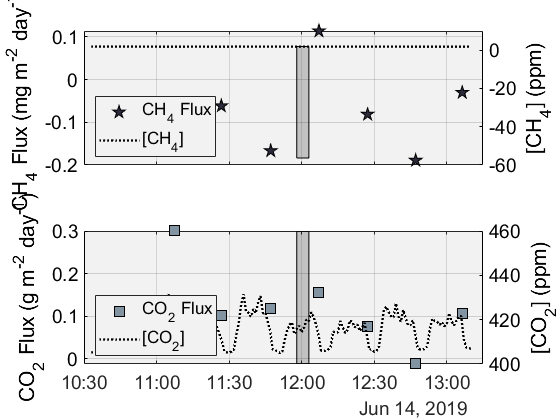

% Resample the d13C isotopes by finding the mean value every minute
    % Daisy (14Jun2019)
TT_DISY_14Jun2019_resamp_1min = retime(TT_DISY_14Jun2019, "minutely", "mean");
    % Daisy (06Jul2018)
TT_DISY_06Jul2018_resamp_1min = retime(TT_DISY_06Jul2018, "minutely", "mean");
    
% Daisy - 14Jun2019    
figure,
% Methane
subplot(2,1,1)
ax1a = gca;
% Plot the Time Series of the Fluxes and the [CH4] pn the same plot
plot(DISY_14Jun2019_Fluxes.End_Time_of_Chamber_Enclosure, DISY_14Jun2019_Fluxes.CH4_Flux, 'kp',                ...
    'MarkerFaceColor', bone_map(50,:), 'MarkerSize', 10);
    %title('CH_4 Fluxes & [CH_4] vs. Time | Daisy (2019)',                                                     ... 
    %      'FontSize', 10)
    ylabel('CH_4 Flux (mg m^{-2} day^{-1})')
    %set(gca, 'XTickLabel', [], 'YLim', [0, 40])
    hold on    

% Plot on the right axis
yyaxis right
ts_CH4 = plot(TT_DISY_14Jun2019_resamp_1min.Time, TT_DISY_14Jun2019_resamp_1min.HP_CH4_dry,                    ...
             ':', 'Color', bone_map(1,:), 'LineWidth', 1.75);
    ylabel('[CH_{4}] (ppm)')
    ax1a.Color            =  bkgrnd_lite;
    ax1a.YAxis(2).Color   = [0.000 0.00 0.000];
    ax1a.FontSize         =  14;
    ax1a.XLim             = datetime(["14-Jun-2019 10:30",  "14-Jun-2019 13:15"]);       
    ax1a.XTickLabels      =  [];
    grid on
    hold on  
    
% Plot Eruption    
    X_area      = eruption_14Jun2019;
    X_area      =[X_area, fliplr(X_area)];
    Y_area      =[ax.YLim(1), ax.YLim(1),  1.90, 1.90];
    fill(X_area(1,:), Y_area(1,:), bone_map(005,:), 'FaceAlpha', 0.20, 'LineStyle', '-')
    legend({'CH_4 Flux', '[CH_4]'}, 'Location', 'southwest')
    hold on
    
% Carbon Dioxide
subplot(2,1,2)
ax1b = gca;
ts_CO2 = plot(DISY_14Jun2019_Fluxes.End_Time_of_Chamber_Enclosure, DISY_14Jun2019_Fluxes.CO2_Flux./1E03, 'ks',           ...
    'MarkerFaceColor', bone_map(150,:), 'MarkerSize', 10);
    %title('CO_2 Fluxes & [CO_2] vs. Time | Daisy (2019)',                                                               ... 
    %      'FontSize', 10)
    ylabel('CO_2 Flux (g m^{-2} day^{-1})')
    %xlim([datetime("26-Oct-2017 11:30"), datetime("26-Oct-2017 19:30")])
    hold on    
    
% Plot on the right axis
yyaxis right
plot(TT_DISY_14Jun2019_resamp_1min.Time, TT_DISY_14Jun2019_resamp_1min.CO2_dry, ':', 'Color', bone_map(1,:),                  ...
    'LineWidth', 1.75)
    ylabel('[CO_2] (ppm)')
    %xlim([datetime("26-Oct-2017 11:30"), datetime("26-Oct-2017 19:30")])
    ax1b.Color          =  bkgrnd_lite;
    ax1b.YAxis(2).Color = [0.000 0.000 0.000];
    ax1b.FontSize       =  14;
    ax1b.XLim           = datetime(["14-Jun-2019 10:30",  "14-Jun-2019 13:15"]);      
    grid on
    hold on
    
% Plot Eruption    
    X_area      = eruption_14Jun2019;
    X_area      =[X_area, fliplr(X_area)];
    Y_area      =[400, 400, 460, 460];
    fill(X_area(1,:), Y_area(1,:), bone_map(005,:), 'FaceAlpha', 0.20, 'LineStyle', '-')
    hold on 
    legend({'CO_2 Flux', '[CO_2]'}, 'Location', 'southwest')

Figure 11: Time series of CH4 (top) and CO2 (bottom) fluxes collected at Daisy Geyser during 2019. The dotted line in each respective plot represent the concentration (60-sec average) through the measurement campaign. The shaded rectangle shows the timing of an eruption.

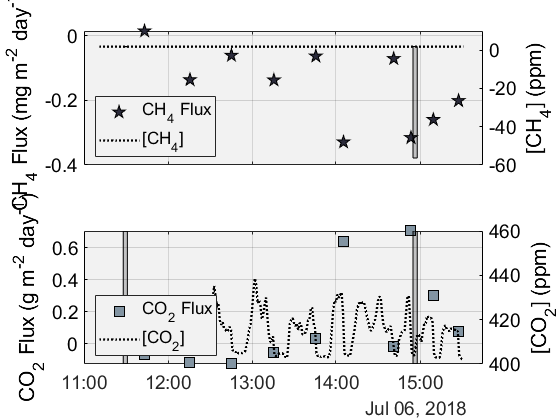

    
% Daisy - 06Jul2018    
figure,
% Methane
subplot(2,1,1)
ax2a = gca;
% Plot the Time Series of the Fluxes and the [CH4] pn the same plot
plot(DISY_06Jul2018_Fluxes.End_Time_of_Chamber_Enclosure, DISY_06Jul2018_Fluxes.CH4_Flux, 'kp',                    ...
    'MarkerFaceColor', bone_map(50,:), 'MarkerSize', 10);
    %title('CH_4 Fluxes & [CH_4] vs. Time | Daisy (2018)',                                                                ... 
    %      'FontSize', 10)
    ylabel('CH_4 Flux (mg m^{-2} day^{-1})')
    %set(gca, 'XTickLabel', [], 'YLim', [0, 40])
    hold on    

% Plot on the right axis
yyaxis right
ts_CH4 = plot(TT_DISY_06Jul2018_resamp_1min.Time, TT_DISY_06Jul2018_resamp_1min.HP_CH4_dry, ':', 'Color', bone_map(1,:),                              ...
    'LineWidth', 1.75);
    ylabel('[CH_{4}] (ppm)')
    ax2a.Color            =  bkgrnd_lite;
    ax2a.YAxis(2).Color   = [0.000 0.00 0.000];
    ax2a.FontSize         =  14;
    ax2a.XLim             = datetime(["06-Jul-2018 11:00",  "06-Jul-2018 15:45"]);  
    ax2a.XTickLabels      =  [];
    grid on
    hold on  
    
% Plot Eruption    
    X_area      = eruption01_06Jul2018;
    X_area      =[X_area, fliplr(X_area)];
    Y_area      =[1.78, 1.78,  1.90, 1.90];
    fill(X_area(1,:), Y_area(1,:), bone_map(005,:), 'FaceAlpha', 0.20, 'LineStyle', '-')
    legend({'CH_4 Flux', '[CH_4]'}, 'Location', 'southwest')
    hold on
% Plot Eruption    
    X_area      = eruption02_06Jul2018;
    X_area      =[X_area, fliplr(X_area)];
    Y_area      =[ax.YLim(1), ax.YLim(1),  1.90, 1.90];
    fill(X_area(1,:), Y_area(1,:), bone_map(005,:), 'FaceAlpha', 0.20, 'LineStyle', '-')
    legend({'CH_4 Flux', '[CH_4]'}, 'Location', 'southwest')
    hold on
    
% Carbon Dioxide
subplot(2,1,2)
ax2b = gca;
ts_CO2 = plot(DISY_06Jul2018_Fluxes.End_Time_of_Chamber_Enclosure, DISY_06Jul2018_Fluxes.CO2_Flux./1E03, 'ks',                                  ...
    'MarkerFaceColor', bone_map(150,:), 'MarkerSize', 10);
    %title('CO_2 Fluxes & [CO_2] vs. Time | Daisy (2018)',                                                               ... 
    %      'FontSize', 10)
    ylabel('CO_2 Flux (g m^{-2} day^{-1})')
    %xlim([datetime("26-Oct-2017 11:30"), datetime("26-Oct-2017 19:30")])
    hold on    
    
% Plot on the right axis
yyaxis right
ax2b = gca;
plot(TT_DISY_06Jul2018_resamp_1min.Time, TT_DISY_06Jul2018_resamp_1min.CO2_dry, ':', 'Color', bone_map(1,:),                  ...
    'LineWidth', 1.75)
    ylabel('[CO_2] (ppm)')
    %xlim([datetime("26-Oct-2017 11:30"), datetime("26-Oct-2017 19:30")])
    ax2b.Color          =  bkgrnd_lite;
    ax2b.YAxis(2).Color = [0.000 0.000 0.000];
    ax2b.FontSize       =  14;
    ax2b.XLim           = datetime(["06-Jul-2018 11:00",  "06-Jul-2018 15:45"]);  
    grid on
    hold on
    
% Plot Eruption    
    X_area      = eruption01_06Jul2018;
    X_area      =[X_area, fliplr(X_area)];
    Y_area      =[400, 400, 460, 460];
    fill(X_area(1,:), Y_area(1,:), bone_map(005,:), 'FaceAlpha', 0.20, 'LineStyle', '-')
    hold on 
    legend({'CO_2 Flux', '[CO_2]'}, 'Location', 'southwest')
% Plot Eruption    
    X_area      = eruption02_06Jul2018;
    X_area      =[X_area, fliplr(X_area)];
    Y_area      =[400, 400, 460, 460];
    fill(X_area(1,:), Y_area(1,:), bone_map(005,:), 'FaceAlpha', 0.20, 'LineStyle', '-')
    hold on 
    legend({'CO_2 Flux', '[CO_2]'}, 'Location', 'southwest')

Figure 12: Time series of CH4 (top) and CO2 (bottom) fluxes collected at Daisy Geyser during 2018. The dotted line in each respective plot repersent the concentration (60-sec average) throught the measurement campaign. The shaded rectangle shows the timing of an eruption.

Re-graphing Flux Times Series based on Reviewers' Suggestions

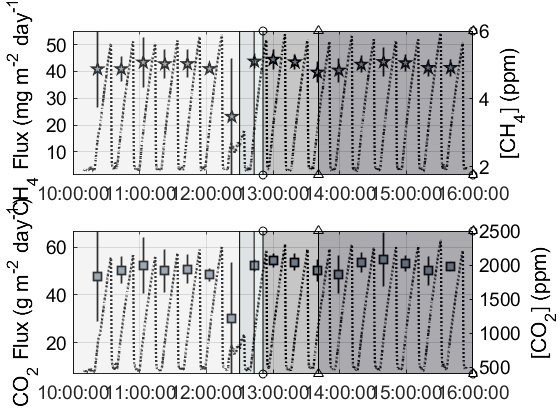

%% Flux Calculation
nchams = 17; H = 0.127;
%----Linear Model Analysis----% 
    % A two-minute equilibration period (approx 33 measurements) is allowed
    % before an assessment of the linear fit.  After this two-minute
    % period, the next three minutes are analyzed (approx. 52 measurements)
    % using a simple linear regression model
        % C_t = b + m*t, where the slope, m, is dC_dt
        
    % Pre-allocate vector for fluxes (per measurement cycle)
    lin_mdl     = cell ([1          nchams      2           ]); 
    lin_slope   = zeros([2          4           nchams     2]);
    lin_flux    = zeros([nchams     3           2           ]);
    
    % Measurement start time
    flx_srt_time= NaT([nchams 1]);    
    % Measurement end time
    flx_end_time= NaT([nchams 1]);
    
    % Use for-loop to run a linear regression for each of the chamber
    % measuerments
    for i = 1:nchams
       %--CH4--%
       
       % To account for the equilibration period at the beginning of the
       % closure period, we bypass the first 120 sec (2 min) of the
       % measurement
            % start
       srt_idx_CH4         = 15;
            % end
       end_idx_CH4         = find(NGBN_STMB_ChamON(:,2,i) <= 240,1, 'last');
       
       % Generate Linear Model
            % Here I chose to go from the start of the of the timeseries to
            % the last non-NaN measurement because all of these
            % measurements were so short on account of the H2O alarms and
            % when CO2 breached 2500 ppm.  No decision has been made if CH4
            % should use data that goes past the CO2 threshold yet (24 Jan
            % 2019)
       lin_mdl{1,i,1}      = fitlm(NGBN_STMB_ChamON(15:end_idx_CH4,02,i),...
                                   NGBN_STMB_ChamON(15:end_idx_CH4,10,i)); 
       % Store pertinent coeffieicents from the linear model                        
       lin_slope(:,:,i,1)  = table2array(lin_mdl{1,i,1}.Coefficients);
       % Quantify the flux for each measurement (mg m^-2 hr^-1)
            % The the "3600" represents one hour in seconds (60 sec * 60
            % min)
       lin_flux(i,1,1)     = lin_slope(2,1,i,1) .* H .* 3600;
       % Quantify Lower Flux (95% CI)
           % Get Conf Limits of slope
           CH4_flx_lims    = coefCI(lin_mdl{1,i,1});
           % Get lower bound
           CH4_flx_lims_lwr= CH4_flx_lims(1,1);
       % Calculate lower flux bound
       lin_flux(i,2,1)     = CH4_flx_lims_lwr .* H .* 3600;
           % Get upper bound
           CH4_flx_lims_upr= CH4_flx_lims(1,2);
       % Calculate upper flux bound
       lin_flux(i,3,1)     = CH4_flx_lims_upr .* H .* 3600;
       
       
       %--CO2--%
       
       % To account for the equilibration period at the beginning of the
       % closure period, we bypass the first 120 sec (2 min) of the
       % measurement  
            % start
       srt_idx_CO2         = 15;
            % end       
       end_idx_CO2         = find(NGBN_STMB_ChamON(:,2,i) <= 240,1, 'last');
       
       % Generate Linear Model
       lin_mdl{1,i,2}      = fitlm(NGBN_STMB_ChamON(15:end_idx_CO2,02,i),...
                                   NGBN_STMB_ChamON(15:end_idx_CO2,11,i)); 
       % Store pertinent coeffieicents from the linear model                        
       lin_slope(:,:,i,2)  = table2array(lin_mdl{1,i,2}.Coefficients);
       % Quantify the flux for each measurement (mg m^-2 hr^-1)
       lin_flux(i,1,2)     = lin_slope(2,1,i,2) .* H .* 3600;
       % Quantify Lower Flux (95% CI)
           % Get Conf Limits of slope
           CO2_flx_lims    = coefCI(lin_mdl{1,i,2});
           % Get lower bound
           CO2_flx_lims_lwr= CO2_flx_lims(1,1);
       % Calculate lower flux bound
       lin_flux(i,2,2)     = CO2_flx_lims_lwr .* H .* 3600;
           % Get upper bound
           CO2_flx_lims_upr= CO2_flx_lims(1,2);
       % Calculate upper flux bound
       lin_flux(i,3,2)     = CO2_flx_lims_upr .* H .* 3600; 
       
       % Pull out the flux measurement end time
            % start
       flx_srt_time(i)   =                                              ...
              datetime(datestr(NGBN_STMB_ChamON(srt_idx_CO2, 1, i)));        
            % end
       flx_end_time(i)   =                                              ...
              datetime(datestr(NGBN_STMB_ChamON(end_idx_CO2, 1, i)));      
       
    end
    
    % Error plot fluxes
    figure,
    % CH4 flux time series
    subplot(2,1,1)
    ax                = gca;
    err_range_CH4_flx =(lin_flux(:,3,1) - lin_flux(:,2,1));
    errorbar(datenum(STMB_Fluxes.End_Time_of_Chamber_Enclosure), lin_flux(:,1,1) * 24,                               ...
                     err_range_CH4_flx,                                                                              ...
                    'kp', 'MarkerFaceColor', bone_map(150,:), 'MarkerSize', 9, 'CapSize', 0, 'LineWidth', 1.25);
    ylabel("CH_4 Flux (mg m^{-2} day^{-1})")
    hold on
    % Plot on the right axis
    yyaxis right
    plot(datenum(TT_NGBN_STMB.Time), TT_NGBN_STMB.HP_CH4_dry, ':', 'Color', bone_map(1,:),                           ...
        'LineWidth', 1.75);
    ylabel("[CH_4] (ppm)")
    xtix         =["12-Jun-2019 10:00", "12-Jun-2019 11:00", "12-Jun-2019 12:00", "12-Jun-2019 13:00",               ...
                   "12-Jun-2019 14:00", "12-Jun-2019 15:00", "12-Jun-2019 16:00"];
    ax.XTick     = datenum(xtix);
    ax.XTickLabel= string(timeofday(datetime(xtix)));
    ax.FontSize  = 14;
    ax.Color     = bkgrnd_lite;
    ax.YAxis(2).Color   = [0.000 0.00 0.000];
    axis tight
    grid on
    hold on
% Plot Eruption 
    % (a) Pre steam    
    X_area      = pre_steam;
    X_area      =datenum([X_area, fliplr(X_area)]);
    Y_area      =[1.75, 1.75, 6, 6];
    fill(X_area(1,:), Y_area(1,:), bone_map(255,:), 'FaceAlpha', 0.20, 'LineStyle', '-')
    hold on
    % (b) Pre Play  
    X_area      = pre_play;
    X_area      =datenum([X_area, fliplr(X_area)]);
    Y_area      =[1.75, 1.75, 6, 6];
    fill(X_area(1,:), Y_area(1,:), bone_map(165,:), 'FaceAlpha', 0.20, 'LineStyle', '-')  
    % (c) 
    X_area      = minor_erup;
    X_area      =datenum([X_area, fliplr(X_area)]);
    Y_area      =[1.75, 1.75, 6, 6];
    fill(X_area(1,:), Y_area(1,:), bone_map(205,:), 'FaceAlpha', 0.20, 'LineStyle', '-')
    hold on
    % (d) Liquid-Dominated Phase eruption
    X_area      = eruption;
    X_area      =datenum([X_area, fliplr(X_area)]);
    Y_area      =[1.75, 1.75, 6, 6];
    fill(X_area(1,:), Y_area(1,:), bone_map(025,:), 'FaceAlpha', 0.20, 'LineStyle', '-')
    hold on
    % (e) Steam-Dominated Phase eruption
    X_area      = steam_dom_erup;
    X_area      =datenum([X_area, fliplr(X_area)]);
    Y_area      =[1.75, 1.75, 6, 6];
    fill(X_area(1,:), Y_area(1,:), bone_map(065,:), 'FaceAlpha', 0.20, 'LineStyle', '-')
    % CO2 flux time series
    subplot(2,1,2)
    ax                = gca;
    err_range_CO2_flx = ((lin_flux(:,3,2) - lin_flux(:,2,2)) / 1000);
    errorbar(datenum(STMB_Fluxes.End_Time_of_Chamber_Enclosure), ((lin_flux(:,1,2) * 24) / 1000),                               ...
                     err_range_CO2_flx,                                                                              ...
                    'ks', 'MarkerFaceColor', bone_map(150,:), 'MarkerSize', 9, 'CapSize', 0, 'LineWidth', 1.25);
    ylabel("CO_2 Flux (g m^{-2} day^{-1})")
    hold on
    % Plot on the right axis
    yyaxis right
    plot(datenum(TT_NGBN_STMB.Time), TT_NGBN_STMB.CO2_dry, ':', 'Color', bone_map(1,:),                           ...
        'LineWidth', 1.75);
    ylabel("[CO_2] (ppm)")
    xtix         =["12-Jun-2019 10:00", "12-Jun-2019 11:00", "12-Jun-2019 12:00", "12-Jun-2019 13:00",               ...
                   "12-Jun-2019 14:00", "12-Jun-2019 15:00", "12-Jun-2019 16:00"];
    ax.XTick     = datenum(xtix);
    ax.XTickLabel= string(timeofday(datetime(xtix)));
    ax.FontSize  = 14;
    ax.Color     = bkgrnd_lite;
    ax.YAxis(2).Color   = [0.000 0.00 0.000];
    axis tight
    grid on
    hold on
% Plot Eruption 
    % (a) Pre steam    
    X_area      = pre_steam;
    X_area      =datenum([X_area, fliplr(X_area)]);
    Y_area      =[400, 400, 2500, 2500];
    fill(X_area(1,:), Y_area(1,:), bone_map(255,:), 'FaceAlpha', 0.20, 'LineStyle', '-')
    hold on
    % (b) Pre Play  
    X_area      = pre_play;
    X_area      =datenum([X_area, fliplr(X_area)]);
    Y_area      =[400, 400, 2500, 2500];
    fill(X_area(1,:), Y_area(1,:), bone_map(165,:), 'FaceAlpha', 0.20, 'LineStyle', '-')  
    % (c) 
    X_area      = minor_erup;
    X_area      =datenum([X_area, fliplr(X_area)]);
    Y_area      =[400, 400, 2500, 2500];
    fill(X_area(1,:), Y_area(1,:), bone_map(205,:), 'FaceAlpha', 0.20, 'LineStyle', '-')
    hold on
    % (d) Liquid-Dominated Phase eruption
    X_area      = eruption;
    X_area      =datenum([X_area, fliplr(X_area)]);
    Y_area      =[400, 400, 2500, 2500];
    fill(X_area(1,:), Y_area(1,:), bone_map(025,:), 'FaceAlpha', 0.20, 'LineStyle', '-')
    hold on
    % (e) Steam-Dominated Phase eruption
    X_area      = steam_dom_erup;
    X_area      =datenum([X_area, fliplr(X_area)]);
    Y_area      =[400, 400, 2500, 2500];
    fill(X_area(1,:), Y_area(1,:), bone_map(065,:), 'FaceAlpha', 0.20, 'LineStyle', '-')

### Extra Functions

    function plot_eruption(erup_dt, plt_shade, gas)
    % PLOT_ERUPTION: this function plots a rectantangle to represent a 
    % range of time for an eruption or feature of an eruption
    % erup_dt: this object needs to be a 1x2 datetime object - dd-mmm-yyyy
    % HH:MM:SS
    % plt_shade: using the bone color scale, indicate a number that is 
    % between 1 and 256, where the latter represents the lightest color
        % Establish the bone map scale
        bone_map    = bone();
        % Plot Eruption    
        X_area      = erup_dt;
        X_area      =[X_area, fliplr(X_area)];
        if strcmp(gas,  "CH4") == 1
           Y_area      =[01, 01, 06, 06];
        else
           Y_area      =[250, 250, 2500, 2500]; 
        end
        fill(X_area(1,:), Y_area(1,:), bone_map(plt_shade,:), 'FaceAlpha', 0.20, 'LineStyle', '-')
    end